clear;close all;clc;

center1 = [ -1.080686481235308,-1.4868554961566771,-0.13921178767435452];
center2 = [-0.39691027324242706,-0.47004061729054947,-0.13921178767435452];
Mcenter = center1;
phi = pi./4;

MTaon = [-0.5580289815934402,-0.8298214601357259,0];

Mradial =  0.6009384528809537;

shenglunum = 4;


testPointShiCe = [-0.866463012	-0.609405895	-0.877730222	-0.660711957	-0.881500475	-0.615953466	-0.84311011	-0.691439605;...
    -0.610885621	-1.424460844	-0.180010849	-1.903962838	-0.179738214	-1.764969917	-0.539231217	-1.439512979;...
    -0.649335997	-0.625697606	-0.349936467	-0.320816915	0.063957982	0.073784916	0.337914976	0.357628615];

[Distance,theta,LTPY,TiC,Wquanzhong1,Wquanzhong2]=YuanXingFuCe(...
    testPointShiCe,shenglunum,Mcenter,MTaon,Mradial,phi)

Distance =     0.8535    1.7378    1.6073    0.9132


theta =     0.8983    0.7174    0.7580    0.7592


LTPY =    -0.0033    0.0100   -0.0327   -0.1087


TiC =    -0.8300   -0.3268    0.3464    0.8109


Wquanzhong1 =     0.3358
    0.6526
    0.6075
    0.3363


Wquanzhong2 =     0.3326
    0.6523
    0.6111
    0.3286


## 2、画图

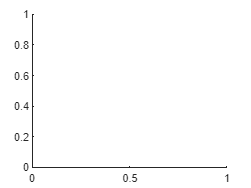

figure
hold on

% % 绘制圆柱面
% plotcylinder(center1,center2,'b',Mradial,0.2)
% xlabel('x')
% ylabel('y')
% zlabel('z')
% axis equal
% camlight;
% lighting flat;

% scatter3(testPointShiCe(1,1),testPointShiCe(2,1),testPointShiCe(3,1),20,'filled','green')
% text(testPointShiCe(1,1),testPointShiCe(2,1),testPointShiCe(3,1),'A1')
% scatter3(testPointShiCe(1,2),testPointShiCe(2,2),testPointShiCe(3,2),20,'filled','green')
% text(testPointShiCe(1,2),testPointShiCe(2,2),testPointShiCe(3,2),'A2')
% scatter3(testPointShiCe(1,3),testPointShiCe(2,3),testPointShiCe(3,3),20,'filled','green')
% text(testPointShiCe(1,3),testPointShiCe(2,3),testPointShiCe(3,3),'A3')
% scatter3(testPointShiCe(1,4),testPointShiCe(2,4),testPointShiCe(3,4),20,'filled','green')
% text(testPointShiCe(1,4),testPointShiCe(2,4),testPointShiCe(3,4),'A4')
% scatter3(testPointShiCe(1,5),testPointShiCe(2,5),testPointShiCe(3,5),20,'filled','green')
% text(testPointShiCe(1,5),testPointShiCe(2,5),testPointShiCe(3,5),'A5')
% scatter3(testPointShiCe(1,6),testPointShiCe(2,6),testPointShiCe(3,6),20,'filled','green')
% text(testPointShiCe(1,6),testPointShiCe(2,6),testPointShiCe(3,6),'A6')
% scatter3(testPointShiCe(1,7),testPointShiCe(2,7),testPointShiCe(3,7),20,'filled','green')
% text(testPointShiCe(1,7),testPointShiCe(2,7),testPointShiCe(3,7),'A7')
% scatter3(testPointShiCe(1,8),testPointShiCe(2,8),testPointShiCe(3,8),20,'filled','green')
% text(testPointShiCe(1,8),testPointShiCe(2,8),testPointShiCe(3,8),'A8')

## 3、投影

Pt = (testPointShiCe(:,3)+testPointShiCe(:,4))./2

Pt =    -0.7692
   -1.0420
   -0.3354


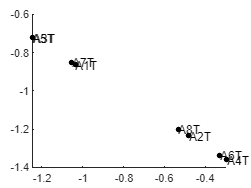


[xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(Pt,center1,center2);
temp = [xN1;yN1;zN1];
nnn = MTaon; %法


% 平面法向量
A = nnn(1);
B = nnn(2);
C = nnn(3);
D = -(A.*xN1+B.*yN1+C.*zN1);

TouYing = zeros(3,2*shenglunum);
for i =1:2*shenglunum
    % 空间点坐标
    x0 = testPointShiCe(1,i);
    y0 = testPointShiCe(2,i);
    z0 = testPointShiCe(3,i);
    
    % 计算投影点
    t = -(A*x0 + B*y0 + C*z0 + D) / (A^2 + B^2 + C^2);
    x_proj = x0 + A * t;
    y_proj = y0 + B * t;
    z_proj = z0 + C * t;
    
    % 返回投影点
    P_projected1 = [x_proj, y_proj, z_proj];
    TouYing(:,i) = P_projected1';
end

scatter3(TouYing(1,1),TouYing(2,1),TouYing(3,1),20,'filled','black')
text(TouYing(1,1),TouYing(2,1),TouYing(3,1),'A1T')
scatter3(TouYing(1,2),TouYing(2,2),TouYing(3,2),20,'filled','black')
text(TouYing(1,2),TouYing(2,2),TouYing(3,2),'A2T')
scatter3(TouYing(1,3),TouYing(2,3),TouYing(3,3),20,'filled','black')
text(TouYing(1,3),TouYing(2,3),TouYing(3,3),'A3T')
scatter3(TouYing(1,4),TouYing(2,4),TouYing(3,4),20,'filled','black')
text(TouYing(1,4),TouYing(2,4),TouYing(3,4),'A4T')
scatter3(TouYing(1,5),TouYing(2,5),TouYing(3,5),20,'filled','black')
text(TouYing(1,5),TouYing(2,5),TouYing(3,5),'A5T')
scatter3(TouYing(1,6),TouYing(2,6),TouYing(3,6),20,'filled','black')
text(TouYing(1,6),TouYing(2,6),TouYing(3,6),'A6T')
scatter3(TouYing(1,7),TouYing(2,7),TouYing(3,7),20,'filled','black')
text(TouYing(1,7),TouYing(2,7),TouYing(3,7),'A7T')
scatter3(TouYing(1,8),TouYing(2,8),TouYing(3,8),20,'filled','black')
text(TouYing(1,8),TouYing(2,8),TouYing(3,8),'A8T')

## 画圆

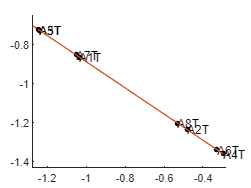

n=nnn; %法向量n
r=Mradial; %圆的半径为1
c=temp; %圆心的坐标
theta=(0:2*pi/100:2*pi)'; %theta角从0到2*pi
a=cross(n,[1 0 0]); %n与i叉乘，求取a向量
if ~any(a) %如果a为零向量，将n与j叉乘
    a=cross(n,[0 1 0]);
end
b=cross(n,a); %求取b向量
a=a/norm(a); %单位化a向量
b=b/norm(b); %单位化b向量

c1=c(1)*ones(size(theta,1),1);
c2=c(2)*ones(size(theta,1),1);
c3=c(3)*ones(size(theta,1),1);

x=c1+r*a(1)*cos(theta)+r*b(1)*sin(theta);%圆上各点的x坐标
y=c2+r*a(2)*cos(theta)+r*b(2)*sin(theta);%圆上各点的y坐标
z=c3+r*a(3)*cos(theta)+r*b(3)*sin(theta);%圆上各点的z坐标

plot3(x,y,z)

axis equal